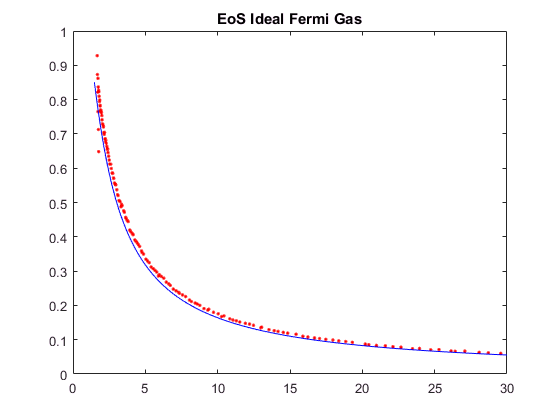

%% Perfect Fake data
PolarizedDataGenerator_Modified;
dE = 0.02;
E0 = (0:dE:7)';
startstep = 0.002; 

allk = []; allP = [];
start = 0; counter = 0;
while start<dE
    [k,P] = EoS_nz_KvsP( y_vec, n_simulated,'plot_maxU',6,'UkHz',(start:dE:7)','diffsize',0,'plot',0);
    allk = [allk;k]; allP = [allP;P]; start = start + startstep; counter = counter + 1;
end
figure; plot(allP,allk,'r.',PTilde,KappaTilde,'b-'); xlim([0 30]); ylim([0 1]); title('EoS Ideal Fermi Gas');

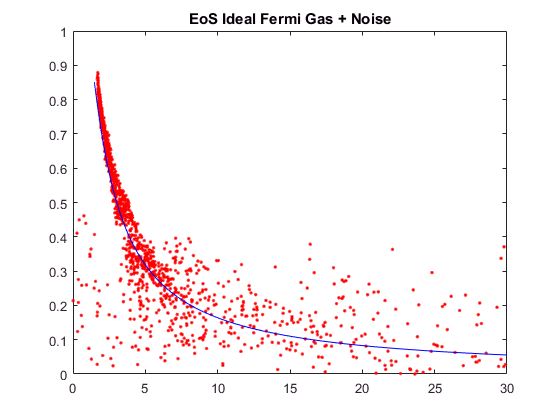

%% Noisy data
averages = 10;
allk = []; allP = [];
for i = 1:averages
    PolarizedDataGenerator_Modified;
    dE = 0.02;
    E0 = (0:dE:7)';
    startstep = 0.002; 
    start = 0; counter = 0;
    while start<dE
        [k,P, U_i, EF_U, n_U, index1, index2 ] = EoS_nz_KvsP( y_vec, n_simulated_noise,'plot_maxU',6,'UkHz',(start:dE:7)','diffsize',0,'plot',0,'Urange',[0.01 1]);
        allk = [allk;k(index1:index2)]; allP = [allP;P(index1:index2)]; start = start + startstep; counter = counter + 1;
    end
    
end
figure; plot(allP,allk,'r.',PTilde,KappaTilde,'b-'); xlim([0 30]); ylim([0 1]); title('EoS Ideal Fermi Gas + Noise');